## [Logistic Regression](https://apmonitor.com/pds/index.php/Main/LogisticRegression)

Logistic regression is a machine learning algorithm for classification. In this algorithm, the probabilities describing the possible outcomes of a single trial are modeled using a logistic function.

Logistic regression makes a binary classification prediction based on the sigmoid function with *n* input features, $x_1 \ldotp \ldotp \ldotp x_n$.


$$p=\frac{1}{1+e^{-\left(\beta_0 +\beta_1 x_1 +\ldotp \ldotp \ldotp +\beta_n x_n \right)} }$$


The $\beta_i$ are coefficients that can be determined from a stochastic gradient descent or other optimization on the training dataset. The desired classification is either a 0 or 1, so the probability calculated with the sigmoid function is rounded to the nearest value.

**Advantages:** Logistic regression is designed for this purpose (classification), and is most useful for understanding the influence of several independent variables on a single outcome variable.

**Disadvantages:** Assumes all predictors are independent of each other, and assumes data set is free of missing values.

#### **Optical Character Recognition with Logistic Regression**

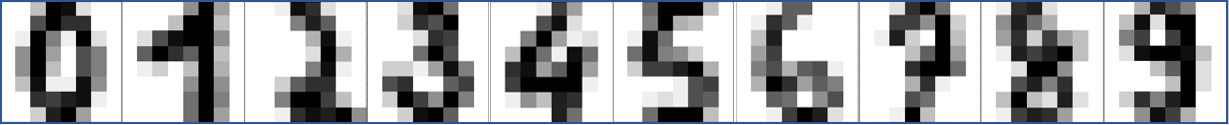

Optical character recognition (OCR) is a method used to convert images of text into machine-readable text. It is typically used to process scanned documents and recognize the text in the images. Logistic regression is a type of machine learning model that can be used for classification tasks. In the context of OCR, logistic regression could be trained to recognize characters in images of text.

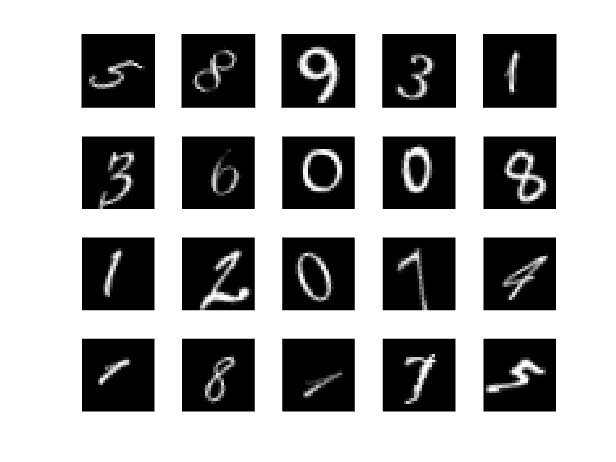

% Import dataset of numbers
digitDatasetPath = fullfile(matlabroot,'toolbox','nnet','nndemos', ...
    'nndatasets','DigitDataset');
imds = imageDatastore(digitDatasetPath, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');

% Show example of dataset
figure;
perm = randperm(10000,20);
for i = 1:20
    subplot(4,5,i);
    imshow(imds.Files{perm(i)});
end

n_samples = length(imds.Files);

% Extract the images into a matrix
X_data = cell(n_samples, 1);
for i = 1:n_samples
    [X_data{i}] = deal(reshape(readimage(imds,i)',[1,28*28]));
end
X_data = cell2mat(X_data);

% Save the labels of the images
Y_data = imds.Labels(1:n_samples);

% Split the data 50% training adn 50% testing
[trainInd,~,testInd] = dividerand(n_samples,0.5,0,0.5);

X_Train = X_data(trainInd,:);
X_Test = X_data(testInd,:);
Y_Train = Y_data(trainInd,:);
Y_Test = Y_data(testInd,:);

X_Train = array2table(im2double(X_Train));

% Create fit (original)
trainingData = X_Train;
responseData = Y_Train;

% Auto-generated by MATLAB on 21-Oct-2023 20:28:34
% Extract predictors and response
% This code processes the data into the right shape for training the
% model.
inputTable = trainingData;
predictorNames = {'Var1', 'Var2', 'Var3', 'Var4', 'Var5', 'Var6', 'Var7', 'Var8', 'Var9', 'Var10', 'Var11', 'Var12', 'Var13', 'Var14', 'Var15', 'Var16', 'Var17', 'Var18', 'Var19', 'Var20', 'Var21', 'Var22', 'Var23', 'Var24', 'Var25', 'Var26', 'Var27', 'Var28', 'Var29', 'Var30', 'Var31', 'Var32', 'Var33', 'Var34', 'Var35', 'Var36', 'Var37', 'Var38', 'Var39', 'Var40', 'Var41', 'Var42', 'Var43', 'Var44', 'Var45', 'Var46', 'Var47', 'Var48', 'Var49', 'Var50', 'Var51', 'Var52', 'Var53', 'Var54', 'Var55', 'Var56', 'Var57', 'Var58', 'Var59', 'Var60', 'Var61', 'Var62', 'Var63', 'Var64', 'Var65', 'Var66', 'Var67', 'Var68', 'Var69', 'Var70', 'Var71', 'Var72', 'Var73', 'Var74', 'Var75', 'Var76', 'Var77', 'Var78', 'Var79', 'Var80', 'Var81', 'Var82', 'Var83', 'Var84', 'Var85', 'Var86', 'Var87', 'Var88', 'Var89', 'Var90', 'Var91', 'Var92', 'Var93', 'Var94', 'Var95', 'Var96', 'Var97', 'Var98', 'Var99', 'Var100', 'Var101', 'Var102', 'Var103', 'Var104', 'Var105', 'Var106', 'Var107', 'Var108', 'Var109', 'Var110', 'Var111', 'Var112', 'Var113', 'Var114', 'Var115', 'Var116', 'Var117', 'Var118', 'Var119', 'Var120', 'Var121', 'Var122', 'Var123', 'Var124', 'Var125', 'Var126', 'Var127', 'Var128', 'Var129', 'Var130', 'Var131', 'Var132', 'Var133', 'Var134', 'Var135', 'Var136', 'Var137', 'Var138', 'Var139', 'Var140', 'Var141', 'Var142', 'Var143', 'Var144', 'Var145', 'Var146', 'Var147', 'Var148', 'Var149', 'Var150', 'Var151', 'Var152', 'Var153', 'Var154', 'Var155', 'Var156', 'Var157', 'Var158', 'Var159', 'Var160', 'Var161', 'Var162', 'Var163', 'Var164', 'Var165', 'Var166', 'Var167', 'Var168', 'Var169', 'Var170', 'Var171', 'Var172', 'Var173', 'Var174', 'Var175', 'Var176', 'Var177', 'Var178', 'Var179', 'Var180', 'Var181', 'Var182', 'Var183', 'Var184', 'Var185', 'Var186', 'Var187', 'Var188', 'Var189', 'Var190', 'Var191', 'Var192', 'Var193', 'Var194', 'Var195', 'Var196', 'Var197', 'Var198', 'Var199', 'Var200', 'Var201', 'Var202', 'Var203', 'Var204', 'Var205', 'Var206', 'Var207', 'Var208', 'Var209', 'Var210', 'Var211', 'Var212', 'Var213', 'Var214', 'Var215', 'Var216', 'Var217', 'Var218', 'Var219', 'Var220', 'Var221', 'Var222', 'Var223', 'Var224', 'Var225', 'Var226', 'Var227', 'Var228', 'Var229', 'Var230', 'Var231', 'Var232', 'Var233', 'Var234', 'Var235', 'Var236', 'Var237', 'Var238', 'Var239', 'Var240', 'Var241', 'Var242', 'Var243', 'Var244', 'Var245', 'Var246', 'Var247', 'Var248', 'Var249', 'Var250', 'Var251', 'Var252', 'Var253', 'Var254', 'Var255', 'Var256', 'Var257', 'Var258', 'Var259', 'Var260', 'Var261', 'Var262', 'Var263', 'Var264', 'Var265', 'Var266', 'Var267', 'Var268', 'Var269', 'Var270', 'Var271', 'Var272', 'Var273', 'Var274', 'Var275', 'Var276', 'Var277', 'Var278', 'Var279', 'Var280', 'Var281', 'Var282', 'Var283', 'Var284', 'Var285', 'Var286', 'Var287', 'Var288', 'Var289', 'Var290', 'Var291', 'Var292', 'Var293', 'Var294', 'Var295', 'Var296', 'Var297', 'Var298', 'Var299', 'Var300', 'Var301', 'Var302', 'Var303', 'Var304', 'Var305', 'Var306', 'Var307', 'Var308', 'Var309', 'Var310', 'Var311', 'Var312', 'Var313', 'Var314', 'Var315', 'Var316', 'Var317', 'Var318', 'Var319', 'Var320', 'Var321', 'Var322', 'Var323', 'Var324', 'Var325', 'Var326', 'Var327', 'Var328', 'Var329', 'Var330', 'Var331', 'Var332', 'Var333', 'Var334', 'Var335', 'Var336', 'Var337', 'Var338', 'Var339', 'Var340', 'Var341', 'Var342', 'Var343', 'Var344', 'Var345', 'Var346', 'Var347', 'Var348', 'Var349', 'Var350', 'Var351', 'Var352', 'Var353', 'Var354', 'Var355', 'Var356', 'Var357', 'Var358', 'Var359', 'Var360', 'Var361', 'Var362', 'Var363', 'Var364', 'Var365', 'Var366', 'Var367', 'Var368', 'Var369', 'Var370', 'Var371', 'Var372', 'Var373', 'Var374', 'Var375', 'Var376', 'Var377', 'Var378', 'Var379', 'Var380', 'Var381', 'Var382', 'Var383', 'Var384', 'Var385', 'Var386', 'Var387', 'Var388', 'Var389', 'Var390', 'Var391', 'Var392', 'Var393', 'Var394', 'Var395', 'Var396', 'Var397', 'Var398', 'Var399', 'Var400', 'Var401', 'Var402', 'Var403', 'Var404', 'Var405', 'Var406', 'Var407', 'Var408', 'Var409', 'Var410', 'Var411', 'Var412', 'Var413', 'Var414', 'Var415', 'Var416', 'Var417', 'Var418', 'Var419', 'Var420', 'Var421', 'Var422', 'Var423', 'Var424', 'Var425', 'Var426', 'Var427', 'Var428', 'Var429', 'Var430', 'Var431', 'Var432', 'Var433', 'Var434', 'Var435', 'Var436', 'Var437', 'Var438', 'Var439', 'Var440', 'Var441', 'Var442', 'Var443', 'Var444', 'Var445', 'Var446', 'Var447', 'Var448', 'Var449', 'Var450', 'Var451', 'Var452', 'Var453', 'Var454', 'Var455', 'Var456', 'Var457', 'Var458', 'Var459', 'Var460', 'Var461', 'Var462', 'Var463', 'Var464', 'Var465', 'Var466', 'Var467', 'Var468', 'Var469', 'Var470', 'Var471', 'Var472', 'Var473', 'Var474', 'Var475', 'Var476', 'Var477', 'Var478', 'Var479', 'Var480', 'Var481', 'Var482', 'Var483', 'Var484', 'Var485', 'Var486', 'Var487', 'Var488', 'Var489', 'Var490', 'Var491', 'Var492', 'Var493', 'Var494', 'Var495', 'Var496', 'Var497', 'Var498', 'Var499', 'Var500', 'Var501', 'Var502', 'Var503', 'Var504', 'Var505', 'Var506', 'Var507', 'Var508', 'Var509', 'Var510', 'Var511', 'Var512', 'Var513', 'Var514', 'Var515', 'Var516', 'Var517', 'Var518', 'Var519', 'Var520', 'Var521', 'Var522', 'Var523', 'Var524', 'Var525', 'Var526', 'Var527', 'Var528', 'Var529', 'Var530', 'Var531', 'Var532', 'Var533', 'Var534', 'Var535', 'Var536', 'Var537', 'Var538', 'Var539', 'Var540', 'Var541', 'Var542', 'Var543', 'Var544', 'Var545', 'Var546', 'Var547', 'Var548', 'Var549', 'Var550', 'Var551', 'Var552', 'Var553', 'Var554', 'Var555', 'Var556', 'Var557', 'Var558', 'Var559', 'Var560', 'Var561', 'Var562', 'Var563', 'Var564', 'Var565', 'Var566', 'Var567', 'Var568', 'Var569', 'Var570', 'Var571', 'Var572', 'Var573', 'Var574', 'Var575', 'Var576', 'Var577', 'Var578', 'Var579', 'Var580', 'Var581', 'Var582', 'Var583', 'Var584', 'Var585', 'Var586', 'Var587', 'Var588', 'Var589', 'Var590', 'Var591', 'Var592', 'Var593', 'Var594', 'Var595', 'Var596', 'Var597', 'Var598', 'Var599', 'Var600', 'Var601', 'Var602', 'Var603', 'Var604', 'Var605', 'Var606', 'Var607', 'Var608', 'Var609', 'Var610', 'Var611', 'Var612', 'Var613', 'Var614', 'Var615', 'Var616', 'Var617', 'Var618', 'Var619', 'Var620', 'Var621', 'Var622', 'Var623', 'Var624', 'Var625', 'Var626', 'Var627', 'Var628', 'Var629', 'Var630', 'Var631', 'Var632', 'Var633', 'Var634', 'Var635', 'Var636', 'Var637', 'Var638', 'Var639', 'Var640', 'Var641', 'Var642', 'Var643', 'Var644', 'Var645', 'Var646', 'Var647', 'Var648', 'Var649', 'Var650', 'Var651', 'Var652', 'Var653', 'Var654', 'Var655', 'Var656', 'Var657', 'Var658', 'Var659', 'Var660', 'Var661', 'Var662', 'Var663', 'Var664', 'Var665', 'Var666', 'Var667', 'Var668', 'Var669', 'Var670', 'Var671', 'Var672', 'Var673', 'Var674', 'Var675', 'Var676', 'Var677', 'Var678', 'Var679', 'Var680', 'Var681', 'Var682', 'Var683', 'Var684', 'Var685', 'Var686', 'Var687', 'Var688', 'Var689', 'Var690', 'Var691', 'Var692', 'Var693', 'Var694', 'Var695', 'Var696', 'Var697', 'Var698', 'Var699', 'Var700', 'Var701', 'Var702', 'Var703', 'Var704', 'Var705', 'Var706', 'Var707', 'Var708', 'Var709', 'Var710', 'Var711', 'Var712', 'Var713', 'Var714', 'Var715', 'Var716', 'Var717', 'Var718', 'Var719', 'Var720', 'Var721', 'Var722', 'Var723', 'Var724', 'Var725', 'Var726', 'Var727', 'Var728', 'Var729', 'Var730', 'Var731', 'Var732', 'Var733', 'Var734', 'Var735', 'Var736', 'Var737', 'Var738', 'Var739', 'Var740', 'Var741', 'Var742', 'Var743', 'Var744', 'Var745', 'Var746', 'Var747', 'Var748', 'Var749', 'Var750', 'Var751', 'Var752', 'Var753', 'Var754', 'Var755', 'Var756', 'Var757', 'Var758', 'Var759', 'Var760', 'Var761', 'Var762', 'Var763', 'Var764', 'Var765', 'Var766', 'Var767', 'Var768', 'Var769', 'Var770', 'Var771', 'Var772', 'Var773', 'Var774', 'Var775', 'Var776', 'Var777', 'Var778', 'Var779', 'Var780', 'Var781', 'Var782', 'Var783', 'Var784'};
predictors = inputTable(:, predictorNames);
response = responseData;
isCategoricalPredictor = [false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false];
classNames = categorical({'0'; '1'; '2'; '3'; '4'; '5'; '6'; '7'; '8'; '9'});

% Train a classifier
% This code specifies all the classifier options and trains the classifier.
template = templateLinear(...
    'Learner', 'Logistic', ...
    'Lambda', 'auto', ...
    'BetaTolerance', 0.0001);
classificationLinear = fitcecoc(...
    predictors, ...
    response, ...
    'Learners', template, ...
    'ClassNames', classNames);

% Create the result struct with predict function
predictorExtractionFcn = @(t) t(:, predictorNames);
classificationLinearPredictFcn = @(x) predict(classificationLinear, x);
trainedClassifier.predictFcn = @(x) classificationLinearPredictFcn(predictorExtractionFcn(x));

% Add additional fields to the result struct
trainedClassifier.RequiredVariables = {'Var1', 'Var10', 'Var100', 'Var101', 'Var102', 'Var103', 'Var104', 'Var105', 'Var106', 'Var107', 'Var108', 'Var109', 'Var11', 'Var110', 'Var111', 'Var112', 'Var113', 'Var114', 'Var115', 'Var116', 'Var117', 'Var118', 'Var119', 'Var12', 'Var120', 'Var121', 'Var122', 'Var123', 'Var124', 'Var125', 'Var126', 'Var127', 'Var128', 'Var129', 'Var13', 'Var130', 'Var131', 'Var132', 'Var133', 'Var134', 'Var135', 'Var136', 'Var137', 'Var138', 'Var139', 'Var14', 'Var140', 'Var141', 'Var142', 'Var143', 'Var144', 'Var145', 'Var146', 'Var147', 'Var148', 'Var149', 'Var15', 'Var150', 'Var151', 'Var152', 'Var153', 'Var154', 'Var155', 'Var156', 'Var157', 'Var158', 'Var159', 'Var16', 'Var160', 'Var161', 'Var162', 'Var163', 'Var164', 'Var165', 'Var166', 'Var167', 'Var168', 'Var169', 'Var17', 'Var170', 'Var171', 'Var172', 'Var173', 'Var174', 'Var175', 'Var176', 'Var177', 'Var178', 'Var179', 'Var18', 'Var180', 'Var181', 'Var182', 'Var183', 'Var184', 'Var185', 'Var186', 'Var187', 'Var188', 'Var189', 'Var19', 'Var190', 'Var191', 'Var192', 'Var193', 'Var194', 'Var195', 'Var196', 'Var197', 'Var198', 'Var199', 'Var2', 'Var20', 'Var200', 'Var201', 'Var202', 'Var203', 'Var204', 'Var205', 'Var206', 'Var207', 'Var208', 'Var209', 'Var21', 'Var210', 'Var211', 'Var212', 'Var213', 'Var214', 'Var215', 'Var216', 'Var217', 'Var218', 'Var219', 'Var22', 'Var220', 'Var221', 'Var222', 'Var223', 'Var224', 'Var225', 'Var226', 'Var227', 'Var228', 'Var229', 'Var23', 'Var230', 'Var231', 'Var232', 'Var233', 'Var234', 'Var235', 'Var236', 'Var237', 'Var238', 'Var239', 'Var24', 'Var240', 'Var241', 'Var242', 'Var243', 'Var244', 'Var245', 'Var246', 'Var247', 'Var248', 'Var249', 'Var25', 'Var250', 'Var251', 'Var252', 'Var253', 'Var254', 'Var255', 'Var256', 'Var257', 'Var258', 'Var259', 'Var26', 'Var260', 'Var261', 'Var262', 'Var263', 'Var264', 'Var265', 'Var266', 'Var267', 'Var268', 'Var269', 'Var27', 'Var270', 'Var271', 'Var272', 'Var273', 'Var274', 'Var275', 'Var276', 'Var277', 'Var278', 'Var279', 'Var28', 'Var280', 'Var281', 'Var282', 'Var283', 'Var284', 'Var285', 'Var286', 'Var287', 'Var288', 'Var289', 'Var29', 'Var290', 'Var291', 'Var292', 'Var293', 'Var294', 'Var295', 'Var296', 'Var297', 'Var298', 'Var299', 'Var3', 'Var30', 'Var300', 'Var301', 'Var302', 'Var303', 'Var304', 'Var305', 'Var306', 'Var307', 'Var308', 'Var309', 'Var31', 'Var310', 'Var311', 'Var312', 'Var313', 'Var314', 'Var315', 'Var316', 'Var317', 'Var318', 'Var319', 'Var32', 'Var320', 'Var321', 'Var322', 'Var323', 'Var324', 'Var325', 'Var326', 'Var327', 'Var328', 'Var329', 'Var33', 'Var330', 'Var331', 'Var332', 'Var333', 'Var334', 'Var335', 'Var336', 'Var337', 'Var338', 'Var339', 'Var34', 'Var340', 'Var341', 'Var342', 'Var343', 'Var344', 'Var345', 'Var346', 'Var347', 'Var348', 'Var349', 'Var35', 'Var350', 'Var351', 'Var352', 'Var353', 'Var354', 'Var355', 'Var356', 'Var357', 'Var358', 'Var359', 'Var36', 'Var360', 'Var361', 'Var362', 'Var363', 'Var364', 'Var365', 'Var366', 'Var367', 'Var368', 'Var369', 'Var37', 'Var370', 'Var371', 'Var372', 'Var373', 'Var374', 'Var375', 'Var376', 'Var377', 'Var378', 'Var379', 'Var38', 'Var380', 'Var381', 'Var382', 'Var383', 'Var384', 'Var385', 'Var386', 'Var387', 'Var388', 'Var389', 'Var39', 'Var390', 'Var391', 'Var392', 'Var393', 'Var394', 'Var395', 'Var396', 'Var397', 'Var398', 'Var399', 'Var4', 'Var40', 'Var400', 'Var401', 'Var402', 'Var403', 'Var404', 'Var405', 'Var406', 'Var407', 'Var408', 'Var409', 'Var41', 'Var410', 'Var411', 'Var412', 'Var413', 'Var414', 'Var415', 'Var416', 'Var417', 'Var418', 'Var419', 'Var42', 'Var420', 'Var421', 'Var422', 'Var423', 'Var424', 'Var425', 'Var426', 'Var427', 'Var428', 'Var429', 'Var43', 'Var430', 'Var431', 'Var432', 'Var433', 'Var434', 'Var435', 'Var436', 'Var437', 'Var438', 'Var439', 'Var44', 'Var440', 'Var441', 'Var442', 'Var443', 'Var444', 'Var445', 'Var446', 'Var447', 'Var448', 'Var449', 'Var45', 'Var450', 'Var451', 'Var452', 'Var453', 'Var454', 'Var455', 'Var456', 'Var457', 'Var458', 'Var459', 'Var46', 'Var460', 'Var461', 'Var462', 'Var463', 'Var464', 'Var465', 'Var466', 'Var467', 'Var468', 'Var469', 'Var47', 'Var470', 'Var471', 'Var472', 'Var473', 'Var474', 'Var475', 'Var476', 'Var477', 'Var478', 'Var479', 'Var48', 'Var480', 'Var481', 'Var482', 'Var483', 'Var484', 'Var485', 'Var486', 'Var487', 'Var488', 'Var489', 'Var49', 'Var490', 'Var491', 'Var492', 'Var493', 'Var494', 'Var495', 'Var496', 'Var497', 'Var498', 'Var499', 'Var5', 'Var50', 'Var500', 'Var501', 'Var502', 'Var503', 'Var504', 'Var505', 'Var506', 'Var507', 'Var508', 'Var509', 'Var51', 'Var510', 'Var511', 'Var512', 'Var513', 'Var514', 'Var515', 'Var516', 'Var517', 'Var518', 'Var519', 'Var52', 'Var520', 'Var521', 'Var522', 'Var523', 'Var524', 'Var525', 'Var526', 'Var527', 'Var528', 'Var529', 'Var53', 'Var530', 'Var531', 'Var532', 'Var533', 'Var534', 'Var535', 'Var536', 'Var537', 'Var538', 'Var539', 'Var54', 'Var540', 'Var541', 'Var542', 'Var543', 'Var544', 'Var545', 'Var546', 'Var547', 'Var548', 'Var549', 'Var55', 'Var550', 'Var551', 'Var552', 'Var553', 'Var554', 'Var555', 'Var556', 'Var557', 'Var558', 'Var559', 'Var56', 'Var560', 'Var561', 'Var562', 'Var563', 'Var564', 'Var565', 'Var566', 'Var567', 'Var568', 'Var569', 'Var57', 'Var570', 'Var571', 'Var572', 'Var573', 'Var574', 'Var575', 'Var576', 'Var577', 'Var578', 'Var579', 'Var58', 'Var580', 'Var581', 'Var582', 'Var583', 'Var584', 'Var585', 'Var586', 'Var587', 'Var588', 'Var589', 'Var59', 'Var590', 'Var591', 'Var592', 'Var593', 'Var594', 'Var595', 'Var596', 'Var597', 'Var598', 'Var599', 'Var6', 'Var60', 'Var600', 'Var601', 'Var602', 'Var603', 'Var604', 'Var605', 'Var606', 'Var607', 'Var608', 'Var609', 'Var61', 'Var610', 'Var611', 'Var612', 'Var613', 'Var614', 'Var615', 'Var616', 'Var617', 'Var618', 'Var619', 'Var62', 'Var620', 'Var621', 'Var622', 'Var623', 'Var624', 'Var625', 'Var626', 'Var627', 'Var628', 'Var629', 'Var63', 'Var630', 'Var631', 'Var632', 'Var633', 'Var634', 'Var635', 'Var636', 'Var637', 'Var638', 'Var639', 'Var64', 'Var640', 'Var641', 'Var642', 'Var643', 'Var644', 'Var645', 'Var646', 'Var647', 'Var648', 'Var649', 'Var65', 'Var650', 'Var651', 'Var652', 'Var653', 'Var654', 'Var655', 'Var656', 'Var657', 'Var658', 'Var659', 'Var66', 'Var660', 'Var661', 'Var662', 'Var663', 'Var664', 'Var665', 'Var666', 'Var667', 'Var668', 'Var669', 'Var67', 'Var670', 'Var671', 'Var672', 'Var673', 'Var674', 'Var675', 'Var676', 'Var677', 'Var678', 'Var679', 'Var68', 'Var680', 'Var681', 'Var682', 'Var683', 'Var684', 'Var685', 'Var686', 'Var687', 'Var688', 'Var689', 'Var69', 'Var690', 'Var691', 'Var692', 'Var693', 'Var694', 'Var695', 'Var696', 'Var697', 'Var698', 'Var699', 'Var7', 'Var70', 'Var700', 'Var701', 'Var702', 'Var703', 'Var704', 'Var705', 'Var706', 'Var707', 'Var708', 'Var709', 'Var71', 'Var710', 'Var711', 'Var712', 'Var713', 'Var714', 'Var715', 'Var716', 'Var717', 'Var718', 'Var719', 'Var72', 'Var720', 'Var721', 'Var722', 'Var723', 'Var724', 'Var725', 'Var726', 'Var727', 'Var728', 'Var729', 'Var73', 'Var730', 'Var731', 'Var732', 'Var733', 'Var734', 'Var735', 'Var736', 'Var737', 'Var738', 'Var739', 'Var74', 'Var740', 'Var741', 'Var742', 'Var743', 'Var744', 'Var745', 'Var746', 'Var747', 'Var748', 'Var749', 'Var75', 'Var750', 'Var751', 'Var752', 'Var753', 'Var754', 'Var755', 'Var756', 'Var757', 'Var758', 'Var759', 'Var76', 'Var760', 'Var761', 'Var762', 'Var763', 'Var764', 'Var765', 'Var766', 'Var767', 'Var768', 'Var769', 'Var77', 'Var770', 'Var771', 'Var772', 'Var773', 'Var774', 'Var775', 'Var776', 'Var777', 'Var778', 'Var779', 'Var78', 'Var780', 'Var781', 'Var782', 'Var783', 'Var784', 'Var79', 'Var8', 'Var80', 'Var81', 'Var82', 'Var83', 'Var84', 'Var85', 'Var86', 'Var87', 'Var88', 'Var89', 'Var9', 'Var90', 'Var91', 'Var92', 'Var93', 'Var94', 'Var95', 'Var96', 'Var97', 'Var98', 'Var99'};
trainedClassifier.ClassificationLinear = classificationLinear;
trainedClassifier.About = 'This struct is a trained model exported from Classification Learner R2023a.';
trainedClassifier.HowToPredict = sprintf('To make predictions on a new table, T, use: \n  [yfit,scores] = c.predictFcn(T) \nreplacing ''c'' with the name of the variable that is this struct, e.g. ''trainedModel''. \n \nThe table, T, must contain the variables returned by: \n  c.RequiredVariables \nVariable formats (e.g. matrix/vector, datatype) must match the original training data. \nAdditional variables are ignored. \n \nFor more information, see How to predict using an exported model.');

% Extract predictors and response
% This code processes the data into the right shape for training the
% model.
inputTable = trainingData;
predictorNames = {'Var1', 'Var2', 'Var3', 'Var4', 'Var5', 'Var6', 'Var7', 'Var8', 'Var9', 'Var10', 'Var11', 'Var12', 'Var13', 'Var14', 'Var15', 'Var16', 'Var17', 'Var18', 'Var19', 'Var20', 'Var21', 'Var22', 'Var23', 'Var24', 'Var25', 'Var26', 'Var27', 'Var28', 'Var29', 'Var30', 'Var31', 'Var32', 'Var33', 'Var34', 'Var35', 'Var36', 'Var37', 'Var38', 'Var39', 'Var40', 'Var41', 'Var42', 'Var43', 'Var44', 'Var45', 'Var46', 'Var47', 'Var48', 'Var49', 'Var50', 'Var51', 'Var52', 'Var53', 'Var54', 'Var55', 'Var56', 'Var57', 'Var58', 'Var59', 'Var60', 'Var61', 'Var62', 'Var63', 'Var64', 'Var65', 'Var66', 'Var67', 'Var68', 'Var69', 'Var70', 'Var71', 'Var72', 'Var73', 'Var74', 'Var75', 'Var76', 'Var77', 'Var78', 'Var79', 'Var80', 'Var81', 'Var82', 'Var83', 'Var84', 'Var85', 'Var86', 'Var87', 'Var88', 'Var89', 'Var90', 'Var91', 'Var92', 'Var93', 'Var94', 'Var95', 'Var96', 'Var97', 'Var98', 'Var99', 'Var100', 'Var101', 'Var102', 'Var103', 'Var104', 'Var105', 'Var106', 'Var107', 'Var108', 'Var109', 'Var110', 'Var111', 'Var112', 'Var113', 'Var114', 'Var115', 'Var116', 'Var117', 'Var118', 'Var119', 'Var120', 'Var121', 'Var122', 'Var123', 'Var124', 'Var125', 'Var126', 'Var127', 'Var128', 'Var129', 'Var130', 'Var131', 'Var132', 'Var133', 'Var134', 'Var135', 'Var136', 'Var137', 'Var138', 'Var139', 'Var140', 'Var141', 'Var142', 'Var143', 'Var144', 'Var145', 'Var146', 'Var147', 'Var148', 'Var149', 'Var150', 'Var151', 'Var152', 'Var153', 'Var154', 'Var155', 'Var156', 'Var157', 'Var158', 'Var159', 'Var160', 'Var161', 'Var162', 'Var163', 'Var164', 'Var165', 'Var166', 'Var167', 'Var168', 'Var169', 'Var170', 'Var171', 'Var172', 'Var173', 'Var174', 'Var175', 'Var176', 'Var177', 'Var178', 'Var179', 'Var180', 'Var181', 'Var182', 'Var183', 'Var184', 'Var185', 'Var186', 'Var187', 'Var188', 'Var189', 'Var190', 'Var191', 'Var192', 'Var193', 'Var194', 'Var195', 'Var196', 'Var197', 'Var198', 'Var199', 'Var200', 'Var201', 'Var202', 'Var203', 'Var204', 'Var205', 'Var206', 'Var207', 'Var208', 'Var209', 'Var210', 'Var211', 'Var212', 'Var213', 'Var214', 'Var215', 'Var216', 'Var217', 'Var218', 'Var219', 'Var220', 'Var221', 'Var222', 'Var223', 'Var224', 'Var225', 'Var226', 'Var227', 'Var228', 'Var229', 'Var230', 'Var231', 'Var232', 'Var233', 'Var234', 'Var235', 'Var236', 'Var237', 'Var238', 'Var239', 'Var240', 'Var241', 'Var242', 'Var243', 'Var244', 'Var245', 'Var246', 'Var247', 'Var248', 'Var249', 'Var250', 'Var251', 'Var252', 'Var253', 'Var254', 'Var255', 'Var256', 'Var257', 'Var258', 'Var259', 'Var260', 'Var261', 'Var262', 'Var263', 'Var264', 'Var265', 'Var266', 'Var267', 'Var268', 'Var269', 'Var270', 'Var271', 'Var272', 'Var273', 'Var274', 'Var275', 'Var276', 'Var277', 'Var278', 'Var279', 'Var280', 'Var281', 'Var282', 'Var283', 'Var284', 'Var285', 'Var286', 'Var287', 'Var288', 'Var289', 'Var290', 'Var291', 'Var292', 'Var293', 'Var294', 'Var295', 'Var296', 'Var297', 'Var298', 'Var299', 'Var300', 'Var301', 'Var302', 'Var303', 'Var304', 'Var305', 'Var306', 'Var307', 'Var308', 'Var309', 'Var310', 'Var311', 'Var312', 'Var313', 'Var314', 'Var315', 'Var316', 'Var317', 'Var318', 'Var319', 'Var320', 'Var321', 'Var322', 'Var323', 'Var324', 'Var325', 'Var326', 'Var327', 'Var328', 'Var329', 'Var330', 'Var331', 'Var332', 'Var333', 'Var334', 'Var335', 'Var336', 'Var337', 'Var338', 'Var339', 'Var340', 'Var341', 'Var342', 'Var343', 'Var344', 'Var345', 'Var346', 'Var347', 'Var348', 'Var349', 'Var350', 'Var351', 'Var352', 'Var353', 'Var354', 'Var355', 'Var356', 'Var357', 'Var358', 'Var359', 'Var360', 'Var361', 'Var362', 'Var363', 'Var364', 'Var365', 'Var366', 'Var367', 'Var368', 'Var369', 'Var370', 'Var371', 'Var372', 'Var373', 'Var374', 'Var375', 'Var376', 'Var377', 'Var378', 'Var379', 'Var380', 'Var381', 'Var382', 'Var383', 'Var384', 'Var385', 'Var386', 'Var387', 'Var388', 'Var389', 'Var390', 'Var391', 'Var392', 'Var393', 'Var394', 'Var395', 'Var396', 'Var397', 'Var398', 'Var399', 'Var400', 'Var401', 'Var402', 'Var403', 'Var404', 'Var405', 'Var406', 'Var407', 'Var408', 'Var409', 'Var410', 'Var411', 'Var412', 'Var413', 'Var414', 'Var415', 'Var416', 'Var417', 'Var418', 'Var419', 'Var420', 'Var421', 'Var422', 'Var423', 'Var424', 'Var425', 'Var426', 'Var427', 'Var428', 'Var429', 'Var430', 'Var431', 'Var432', 'Var433', 'Var434', 'Var435', 'Var436', 'Var437', 'Var438', 'Var439', 'Var440', 'Var441', 'Var442', 'Var443', 'Var444', 'Var445', 'Var446', 'Var447', 'Var448', 'Var449', 'Var450', 'Var451', 'Var452', 'Var453', 'Var454', 'Var455', 'Var456', 'Var457', 'Var458', 'Var459', 'Var460', 'Var461', 'Var462', 'Var463', 'Var464', 'Var465', 'Var466', 'Var467', 'Var468', 'Var469', 'Var470', 'Var471', 'Var472', 'Var473', 'Var474', 'Var475', 'Var476', 'Var477', 'Var478', 'Var479', 'Var480', 'Var481', 'Var482', 'Var483', 'Var484', 'Var485', 'Var486', 'Var487', 'Var488', 'Var489', 'Var490', 'Var491', 'Var492', 'Var493', 'Var494', 'Var495', 'Var496', 'Var497', 'Var498', 'Var499', 'Var500', 'Var501', 'Var502', 'Var503', 'Var504', 'Var505', 'Var506', 'Var507', 'Var508', 'Var509', 'Var510', 'Var511', 'Var512', 'Var513', 'Var514', 'Var515', 'Var516', 'Var517', 'Var518', 'Var519', 'Var520', 'Var521', 'Var522', 'Var523', 'Var524', 'Var525', 'Var526', 'Var527', 'Var528', 'Var529', 'Var530', 'Var531', 'Var532', 'Var533', 'Var534', 'Var535', 'Var536', 'Var537', 'Var538', 'Var539', 'Var540', 'Var541', 'Var542', 'Var543', 'Var544', 'Var545', 'Var546', 'Var547', 'Var548', 'Var549', 'Var550', 'Var551', 'Var552', 'Var553', 'Var554', 'Var555', 'Var556', 'Var557', 'Var558', 'Var559', 'Var560', 'Var561', 'Var562', 'Var563', 'Var564', 'Var565', 'Var566', 'Var567', 'Var568', 'Var569', 'Var570', 'Var571', 'Var572', 'Var573', 'Var574', 'Var575', 'Var576', 'Var577', 'Var578', 'Var579', 'Var580', 'Var581', 'Var582', 'Var583', 'Var584', 'Var585', 'Var586', 'Var587', 'Var588', 'Var589', 'Var590', 'Var591', 'Var592', 'Var593', 'Var594', 'Var595', 'Var596', 'Var597', 'Var598', 'Var599', 'Var600', 'Var601', 'Var602', 'Var603', 'Var604', 'Var605', 'Var606', 'Var607', 'Var608', 'Var609', 'Var610', 'Var611', 'Var612', 'Var613', 'Var614', 'Var615', 'Var616', 'Var617', 'Var618', 'Var619', 'Var620', 'Var621', 'Var622', 'Var623', 'Var624', 'Var625', 'Var626', 'Var627', 'Var628', 'Var629', 'Var630', 'Var631', 'Var632', 'Var633', 'Var634', 'Var635', 'Var636', 'Var637', 'Var638', 'Var639', 'Var640', 'Var641', 'Var642', 'Var643', 'Var644', 'Var645', 'Var646', 'Var647', 'Var648', 'Var649', 'Var650', 'Var651', 'Var652', 'Var653', 'Var654', 'Var655', 'Var656', 'Var657', 'Var658', 'Var659', 'Var660', 'Var661', 'Var662', 'Var663', 'Var664', 'Var665', 'Var666', 'Var667', 'Var668', 'Var669', 'Var670', 'Var671', 'Var672', 'Var673', 'Var674', 'Var675', 'Var676', 'Var677', 'Var678', 'Var679', 'Var680', 'Var681', 'Var682', 'Var683', 'Var684', 'Var685', 'Var686', 'Var687', 'Var688', 'Var689', 'Var690', 'Var691', 'Var692', 'Var693', 'Var694', 'Var695', 'Var696', 'Var697', 'Var698', 'Var699', 'Var700', 'Var701', 'Var702', 'Var703', 'Var704', 'Var705', 'Var706', 'Var707', 'Var708', 'Var709', 'Var710', 'Var711', 'Var712', 'Var713', 'Var714', 'Var715', 'Var716', 'Var717', 'Var718', 'Var719', 'Var720', 'Var721', 'Var722', 'Var723', 'Var724', 'Var725', 'Var726', 'Var727', 'Var728', 'Var729', 'Var730', 'Var731', 'Var732', 'Var733', 'Var734', 'Var735', 'Var736', 'Var737', 'Var738', 'Var739', 'Var740', 'Var741', 'Var742', 'Var743', 'Var744', 'Var745', 'Var746', 'Var747', 'Var748', 'Var749', 'Var750', 'Var751', 'Var752', 'Var753', 'Var754', 'Var755', 'Var756', 'Var757', 'Var758', 'Var759', 'Var760', 'Var761', 'Var762', 'Var763', 'Var764', 'Var765', 'Var766', 'Var767', 'Var768', 'Var769', 'Var770', 'Var771', 'Var772', 'Var773', 'Var774', 'Var775', 'Var776', 'Var777', 'Var778', 'Var779', 'Var780', 'Var781', 'Var782', 'Var783', 'Var784'};
predictors = inputTable(:, predictorNames);
response = responseData;
isCategoricalPredictor = [false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false];
classNames = categorical({'0'; '1'; '2'; '3'; '4'; '5'; '6'; '7'; '8'; '9'});

% Perform cross-validation
KFolds = 5;
cvp = cvpartition(response, 'KFold', KFolds);
% Initialize the predictions to the proper sizes
validationPredictions = response;
numObservations = size(predictors, 1);
numClasses = 10;
validationScores = NaN(numObservations, numClasses);
for fold = 1:KFolds
    trainingPredictors = predictors(cvp.training(fold), :);
    trainingResponse = response(cvp.training(fold), :);
    foldIsCategoricalPredictor = isCategoricalPredictor;

    % Train a classifier
    % This code specifies all the classifier options and trains the classifier.
    template = templateLinear(...
        'Learner', 'Logistic', ...
        'Lambda', 'auto', ...
        'BetaTolerance', 0.0001);
    classificationLinear = fitcecoc(...
        trainingPredictors, ...
        trainingResponse, ...
        'Learners', template, ...
        'ClassNames', classNames);

    % Create the result struct with predict function
    classificationLinearPredictFcn = @(x) predict(classificationLinear, x);
    validationPredictFcn = @(x) classificationLinearPredictFcn(x);

    % Add additional fields to the result struct

    % Compute validation predictions
    validationPredictors = predictors(cvp.test(fold), :);
    [foldPredictions, foldScores] = validationPredictFcn(validationPredictors);

    % Store predictions in the original order
    validationPredictions(cvp.test(fold), :) = foldPredictions;
    validationScores(cvp.test(fold), :) = foldScores;
end

classifier = classificationLinear;

% Evaluate the model performance on the test set
y_pred = predict(classifier,array2table(im2double(X_Test)));
accuracy = mean(y_pred == Y_Test);
fprintf("Accuracy: %.2f\n", accuracy);

Accuracy: 0.65


Below is an example that also shows a number from the test set that is evaluated with the Logistic Regression classifier.

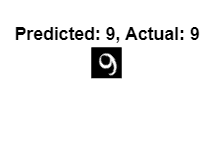

% Select random nummber image
n = randi([0,n_samples],1);

% Get the prediction
reshape(readimage(imds,n)',[1,28*28]);
yp = predict(classifier,im2double(reshape(readimage(imds,n)',[1,28*28])));

% Display the image with the prediction
figure;
imshow(imds.Files{n})
titleText = "Predicted: " + string(yp) + ", Actual: " + string(imds.Labels(n));
title(titleText, 'FontSize', 12)

#### Logistic Regression Programming

Using only MATLAB code (not a machine learning package), create a Logistic Regression classifier. First develop the code to test 2 features. Use the source code blocks as needed.

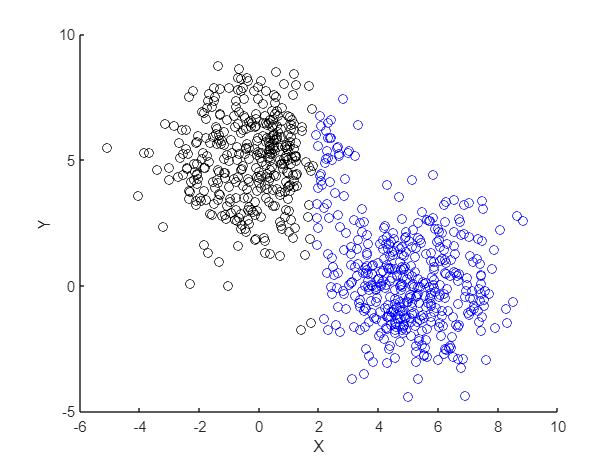

% Create Data
% Set parameters for data
n_samples = 800;
n_features = 2;
centers = [0, 5; 5, 0];
cluster_std = 1.5;

% Create matrixes to hold data
data_val = zeros(n_samples, n_features);
label = zeros(n_samples, 1);

% Create the random data based on previous inputs
for i = 1:2
    idx = ((i-1)*n_samples/2 + 1) : (i*n_samples/2);
    data_val(idx, :) = bsxfun(@plus, centers(i,:), cluster_std*randn(length(idx), n_features));
    label(idx) = i;
end

% Combine the X and Y data
tbl = [array2table(data_val) array2table(label)];
tbl.Properties.VariableNames = ["X","Y","label"];

% Plot Data
figure;
cmap = [0 0 0; 0 0 1];
colormap(cmap)
scatter(tbl,"X","Y","ColorVariable",true);

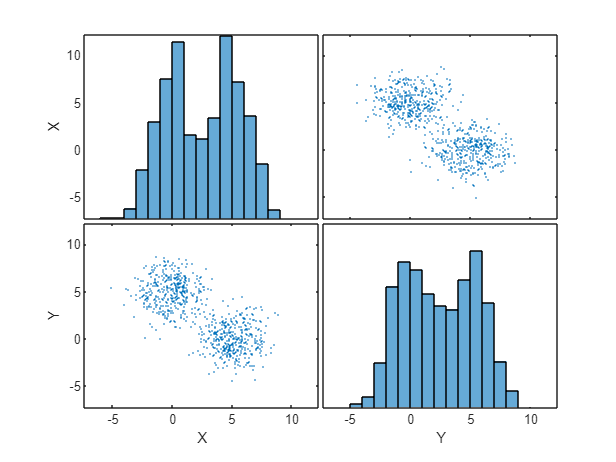


% Plot matrix
figure;
[~, ax, ~, ~, ~] = plotmatrix(table2array(tbl(:,1:end-1)));

for i = 1:2
    xlabel(ax(2,i), tbl.Properties.VariableNames{i})
    ylabel(ax(i,1), tbl.Properties.VariableNames{i})
end

Split data into train (80%) and test (20%) sets.

% Split the data 80% training and 20% testing
[trainInd,~,testInd] = dividerand(n_samples,0.5,0,0.2);

train = tbl(trainInd,:);
test = tbl(testInd,:);

Create a function to make a prediction with coefficients.


$$p=\frac{1}{1+e^{-\left(\beta_0 +\beta_1 x_1 +\ldotp \ldotp \ldotp +\beta_n x_n \right)} }$$


See function section below to view this function.

Update coefficients for the intercept $\beta_0$ with


$$\beta_0 =\beta_0 +l_{\textrm{rate}} \left(\textrm{err}\right)\overset{\wedge }{y} \left(1-\overset{\wedge }{y} \right)$$


and for the feature coefficients $\beta_{i+1}$ with


$$\beta_{i+1} =\beta_{i+1} +l_{\textrm{rate}} \left(\textrm{err}\right)\overset{\wedge }{y} \left(1-\overset{\wedge }{y} \right)x_i$$


where $l_{\textrm{rate}}$ is the learning rate (use 0.3), err is the error (difference) between the measured label y and the predicted label $\overset{\wedge }{y}$, and $x_i$ is the input feature. Continue for 100 epochs (iteration updates of β) and plot the loss function.

% Set parameters for learning model
l_rate = 0.25;
n_epoch = 100;

% Run the model
loss = zeros(n_epoch,1);
beta = [0.0; 0.0; 0.0];
for epoch = 1:n_epoch
    sum_error = 0;
    for i = 1:size(train,1)
        row = table2array(train(i,:));
        x = row(1:end-1); % input features
        y = row(end)-1;     % output label
        yhat = prediction(row, beta);
        error = y - yhat;
        sum_error = sum_error + error^2;
        beta(1) = beta(1) + l_rate * error * yhat * (1.0 - yhat);
        beta(2) = beta(2) + l_rate * error * yhat * (1.0 - yhat) * x(1);
        beta(3) = beta(3) + l_rate * error * yhat * (1.0 - yhat) * x(2);
    end
    loss(epoch) = sum_error; % Save error to loss matrix
end

disp('Coefficients:')

Coefficients:


disp(beta)

   -0.5663
    3.1942
   -2.8640



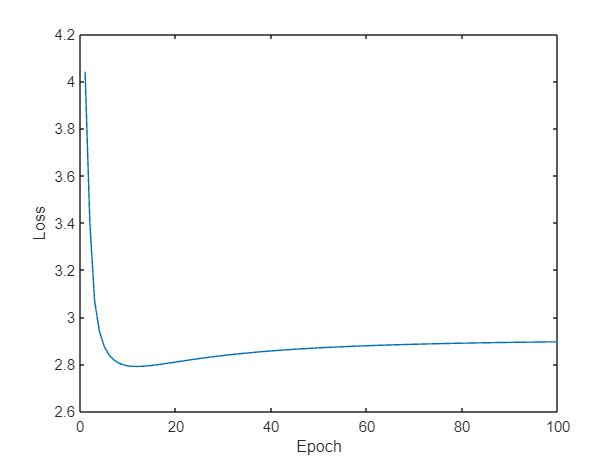

plot(loss);
xlabel('Epoch');
ylabel('Loss');

Occasionally, the loss function will increase for a time and this could be due to a variety of factors. If the learning rate is too large the optimization process can overshoot the minimum, leading to divergence. Though if the learning rate is to small the convergence may be slow. Also the noisier the data is the more the loss function tends to fluctuate. Scaling the data can help alleviate that problem. 

Test the logistic regression model on the remaining 20% the data not used for training.

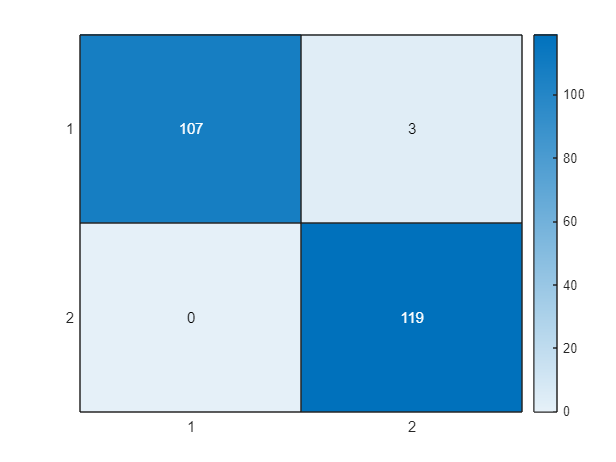

% Calculate yhat based on values calculated above
yhat = zeros(size(test,1),1);
for i = 1:size(test, 1)
    yhat(i) = round(prediction(table2array(test(i,:)), beta)) + 1;
end

% Confusion matrix
cmat = confusionmat(table2array(test(:,"label")), yhat);
heatmap(cmat);

As a final step, make the code general to accept any number of input features. Test with a random integer for *n_features* between 3 and 10.

Supporting Functions

function yhat = prediction(row, beta) % Performs the linear regression model to predict the yhat value based on the inputs beta and the regressed values x
    x = row(1:2);
    yhat = beta(1) + beta(2)*x(1) + beta(3)*x(2);
    yhat = 1.0 / (1.0 + exp(-yhat));
end